# Local Planner Simulation

## function import

addpath("./utils/env/", "./utils/data/map/", "./utils/plot/", "./utils/animation/");
addpath("./local_planner/");
addpath("./global_planner/graph_search/");
addpath("./global_planner/sample_search/");

## initialize

clear all;
clc;

% load environment
load("gridmap_20x20_scene1.mat");
map_size = size(grid_map);
G = 1;

% start and goal pose
start = [3, 2, 0];
goal = [18, 29, pi / 2];

% planner
global_planner_name = "a_star";

local_planner_name = "pid_plan";
% local_planner_name = "dwa_plan";
% local_planner_name = "mpc_plan";

pid_local_planner_name = "pid_plan";
% local_planner_name = "dwa_plan";
mpc_local_planner_name = "mpc_plan";

## Path planning

global_planner = str2func(global_planner_name);
[path, global_flag, cost, expand] = global_planner(grid_map, start(:, 1:2), goal(:, 1:2));

## trajectory planning

% 开始计时
tic;
pid_local_planner = str2func(pid_local_planner_name);
mpc_local_planner = str2func(mpc_local_planner_name);
[pose, traj, local_flag] = pid_local_planner(start, goal, "path", path, "map", grid_map);
pidPath = pose(:, 1:2);  % 假设 traj 的前两列是 x 和 y 坐标
% 结束计时并输出经过的时间
elapsedTime = toc;
fprintf('%s执行时间: %.2f 秒\n', pid_local_planner_name, elapsedTime);

pid_plan执行时间: 0.04 秒


% 开始计时
tic;
[pose, traj, local_flag] = mpc_local_planner(start, goal, "path", path, "map", grid_map);

mpcPath = pose(:, 1:2);  % 假设 traj 的前两列是 x 和 y 坐标
% 结束计时并输出经过的时间
elapsedTime = toc;
fprintf('%s执行时间: %.2f 秒\n', mpc_local_planner_name, elapsedTime);

mpc_plan执行时间: 3.09 秒


## visualization

% 确定需要插值到的点数
numPoints = max(size(pidPath, 1), size(path, 1));

% 对 PID 路径进行插值
interpolatedPidPath = interpolatePath(pidPath, numPoints);

% 对 JPS 路径进行插值
interpolatedPath = interpolatePath(path, numPoints);

% 计算 PID 路径与 JPS 路径的偏差
pidDeviation = calculateDeviation(interpolatedPidPath, interpolatedPath);

% 计算误差 (例如均方误差)
pidError = calculateError(pidDeviation);

% 显示结果
disp(['PID 误差: ' num2str(pidError)]);

PID 误差: 308.2847


% 确定需要插值到的点数
numPoints = max(size(mpcPath, 1), size(path, 1));

% 对 MPC 路径进行插值
interpolatedMpcPath = interpolatePath(mpcPath, numPoints);

% 对 JPS 路径进行插值
interpolatedPath_ = interpolatePath(path, numPoints);

% 计算 MPC 路径与 JPS 路径的偏差
mpcDeviation = calculateDeviation(interpolatedMpcPath, interpolatedPath_);

% 计算误差 (例如均方误差)
mpcError = calculateError(mpcDeviation);

% 显示结果
disp(['MPC 误差: ' num2str(mpcError)]);

MPC 误差: 301.7292


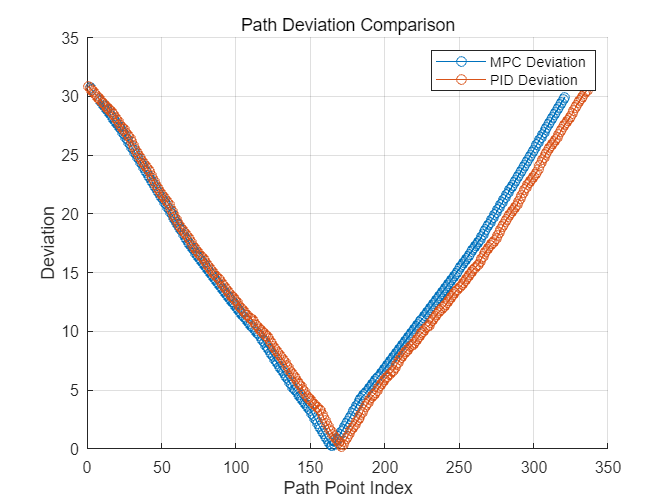


% 绘制偏差曲线图
figure;
hold on;
plot(1:length(mpcDeviation), mpcDeviation, '-o', 'DisplayName', 'MPC Deviation');
plot(1:length(pidDeviation), pidDeviation, '-o', 'DisplayName', 'PID Deviation');
xlabel('Path Point Index');
ylabel('Deviation');
title('Path Deviation Comparison');
legend('show');
grid on;
hold off;

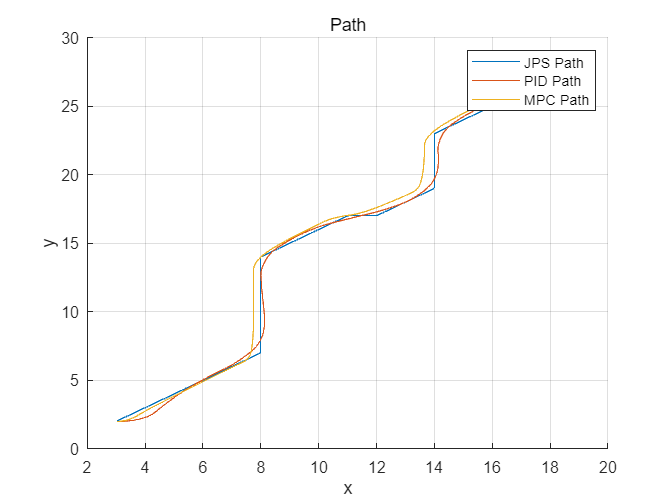

figure;
hold on;
plot(interpolatedPath(:,1),interpolatedPath(:,2), 'DisplayName', 'JPS Path');
plot(interpolatedPidPath(:,1),interpolatedPidPath(:,2), 'DisplayName', 'PID Path')
plot(interpolatedMpcPath(:,1),interpolatedMpcPath(:,2), 'DisplayName', 'MPC Path')
xlabel('x');
ylabel('y');
title('Path');
legend('show');
grid on;
hold off;

clf;
hold on

% plot grid map
plot_grid(grid_map);
plot_path(path, G);

% plot start and goal
plot_square(start, map_size, G, "#f00");
plot_square(goal, map_size, G, "#15c");

% animation
record_video = false;
animation(local_planner_name, pose, traj, G / 2, record_video);

hold off
% 插值路径的函数（示例使用线性插值）

function interpolatedPath = interpolatePath(path, desiredLength)
    x = path(:, 1);
    y = path(:, 2);
    t = linspace(0, 1, size(path, 1));
    ti = linspace(0, 1, desiredLength);
    xi = interp1(t, x, ti);
    yi = interp1(t, y, ti);
    interpolatedPath = [xi(:), yi(:)];
end

% 计算路径偏差的函数
function deviation = calculateDeviation(path1, path2)
    % 确保路径长度相同
    if size(path1, 1) ~= size(path2, 1)
        error('Paths must have the same number of points.');
    end
    
    % 计算每个对应点之间的欧几里得距离
    deviation = sqrt(sum((path1 - path2).^2, 2));
end

% 计算误差的函数
function error = calculateError(deviation)
    % 计算均方误差 (MSE)
    error = mean(deviation.^2);
end